clear;
for i = 1:3
    for j = 1:3
        for k = 1:5
            A(i,j,k) = i + 2*j;
        end
    end
end

A

A = A(:,:,1) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,2) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,3) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,4) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,5) =

     3     5     7
     4     6     8
     5     7     9



B = reshape(A,[],5)

B =      3     3     3     3     3
     4     4     4     4     4
     5     5     5     5     5
     5     5     5     5     5
     6     6     6     6     6
     7     7     7     7     7
     7     7     7     7     7
     8     8     8     8     8
     9     9     9     9     9



clear;
M = 10;
N = ceil(M/2);
orig_dom_X1 = linspace(-pi/2,pi/2,M);
orig_dom_Y1 = linspace(-pi/2,pi/2,N)

orig_dom_Y1 =    -1.5708   -0.7854         0    0.7854    1.5708


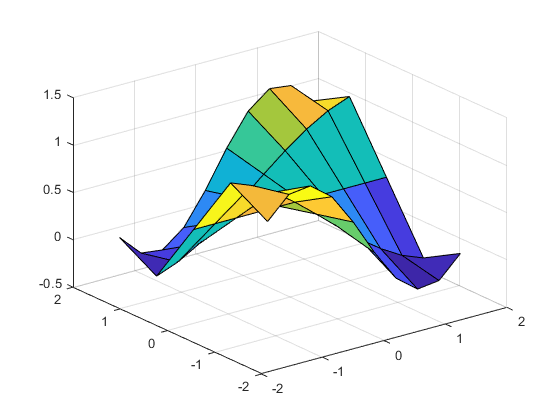

[X,Y] = ndgrid(orig_dom_X1,orig_dom_Y1);

for i = 1:88
    m = rand;
    b = rand;
    A(:,:,i) = m*sin(X.*Y) + b;
end
surf(X,Y,A(:,:,5))


s = size(A);

B = reshape(A,[],s(end))

B =     0.0923    0.8262    0.5429    0.3038    0.9353    1.1436    0.4593    1.0458    1.4195    0.1143    0.6306    1.2643    0.5767    1.0138    0.1713    0.2795    0.3182    0.7039    1.0491    1.2725    0.5592    0.9465    1.3604    0.8234    1.5021    1.5623    0.4628    0.8306    1.2333    0.8831    0.8496    0.8867    0.7752    1.0896    1.0954    0.5511    1.0331    0.6490    0.4332    1.3403    1.1091    1.5357    0.9629    0.4868    0.8363    0.4040    0.7029    0.6873    0.3267    0.4204
    0.1365    1.1301    0.6016    0.3358    1.1601    1.3964    0.6132    1.2670    1.6987    0.1469    0.9443    1.4553    0.8402    1.0507    0.1798    0.4002    0.3365    0.7704    1.2370    1.5198    0.6290    1.0934    1.6623    0.9668    1.8139    1.8661    0.4628    0.9945    1.3996    0.9140    1.0833    0.9894    1.0763    1.2914    1.3997    0.7226    1.3003    0.9185    0.5338    1.6181    1.3609    1.8146    1.2338    0.5424    0.9525    0.5173    0.8329    0.8915    0.3589    0

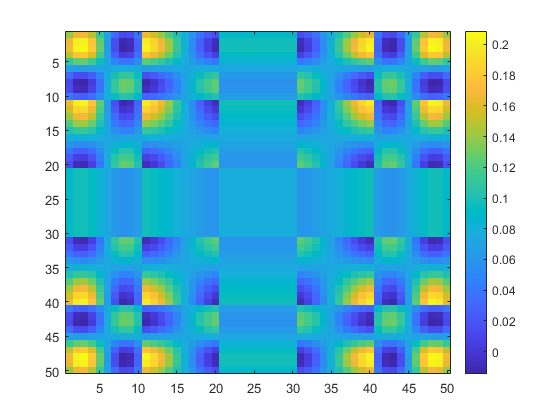

B = B';

C_B = cov(B);
imagesc(C_B)
colorbar


% 'If I reshape this^ image correctly, I should get a 4D array that varies smoothly on each of its 4 axes'
disp(['If I reshape this^ image correctly,' newline 'I should get a 4D array that ' newline 'varies smoothly on each of its 4 axes.'])

If I reshape this^ image correctly,
I should get a 4D array that 
varies smoothly on each of its 4 axes.



disp(['A good way to check if I''m reshaping it' newline 'properly or not would be to' newline 'reshape, interpolate, reshape, and plot.'])

A good way to check if I'm reshaping it
properly or not would be to
reshape, interpolate, reshape, and plot.



C = reshape(C_B,M,N,M,N);
disp('size of C')

size of C


size(C)

ans =     10     5    10     5


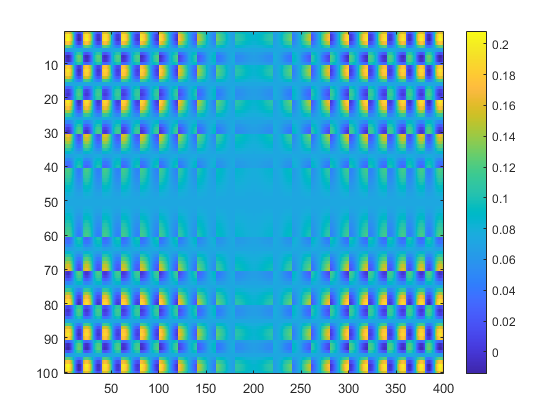


N_h = 2*N;
M_h = 2*M;

new_dom_X1 = linspace(-pi/2,pi/2,N_h);
new_dom_Y1 = linspace(-pi/2,pi/2,N_h);
new_dom_X2 = linspace(-pi/2,pi/2,M_h);
new_dom_Y2 = linspace(-pi/2,pi/2,M_h);

% [X1_h,Y1_h,X2_h,Y2_h] = ndgrid(new_dom_X1,new_dom_Y1,new_dom_X2,new_dom_Y2);
wv_i = [new_dom_X1; new_dom_Y1]; wv_j = [new_dom_X2; new_dom_Y2];

C_B_high_def = covariance_function(wv_i,wv_j,orig_dom_X1,orig_dom_Y1,C_B);

imagesc(C_B_high_def)
colorbar


disp('This is awesome and meta.')

This is awesome and meta.
